# Plotting Transfer Functions

We wish to solve the differential equation of an RC circuit

$RC\dot{v} \left(t\right)+v\left(t\right)=u\left(t\right)$.

Rather than dealing with a differential equation, we take advantage of the Laplace transform to make the following replacements:


$$\begin{array}{l}
u\left(t\right)\longrightarrow \;\;U\left(s\right)\\
x\left(t\right)\longrightarrow \;\;X\left(s\right)\\
\dot{x} \left(t\right)\longrightarrow sX\left(s\right)
\end{array}$$


Leading to $\textrm{RCs}V\left(s\right)+V\left(s\right)=U\left(s\right)$ or, equivalently,

$V\left(s\right)=T\left(s\right)\;U\left(s\right)$,

where


$$T\left(s\right)=\frac{1}{1+\textrm{RCs}}$$


is known as the **transfer function**. The function $T\left(s\right)$ contains all the information needed to characterize the solution to the original differential equation, if you know where to look.

We begin or study by defining a grid for our complex variable $s=\sigma +j\omega \;$, with $\sigma \in \left\lbrack -2000,2000\right\rbrack$ and $\omega \in \left\lbrack -2000,2000\right\rbrack$.

sigma = linspace(-2000,2000);
omega = linspace(-2000,2000);

s = sigma + 1j*omega';  % The transpose turns s into a matrix

We now define the transfer function $T\left(s\right)$, given $R=100\;\Omega \;$ and $C=10\;\mu F$.

R = 100;
C = 10e-6;
z = 0.2;
TF = 1./(R*C*s+1);

## Poles

Given a function $T\left(s\right)$, a pole $p$ is any value such that $T\left(p\right)=\infty \;$.

If we plot $T\left(s\right)$, we see that the function has a single peak in $s\approx -1000$, which corresponds to the pole 


$$p=-\frac{1}{\textrm{RC}}$$


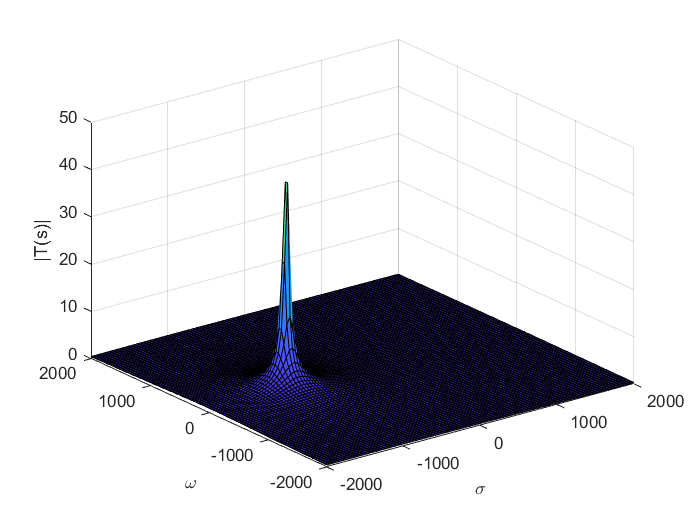

surf(sigma,omega,abs(TF))
xlabel('\sigma')
ylabel('\omega')
zlabel('|T(s)|')

Incidentally, if we were to solve the unforced system dynamics

$\textrm{RC}\dot{v} \left(t\right)+v\left(t\right)=0$,

we would obtain the solution


$$v\left(t\right)=v_0 \;e^{\textrm{pt}} ,$$


where $p=-\frac{1}{\textrm{RC}}$ is the same value obtained by computing the pole of $T\left(s\right)$.

## deciBel Scaling: z axis

Since $\lim_{s\to p} T\left(s\right)=\infty \;$, plotting $\left|T\left(s\right)\right|$ for all ***OTHER*** values of $s$ is actually quite difficult because every other value is comparatively very small. To circumvent this issue, it is customary to use a ***deciBel ***plot, where

$\textrm{dB}\left(|T\left(s\right)|\right)=20\;\log_{10} \left(|T\left(s\right)|\right)$.

This makes figures with very different scaling factors somewhat easier to interpret.

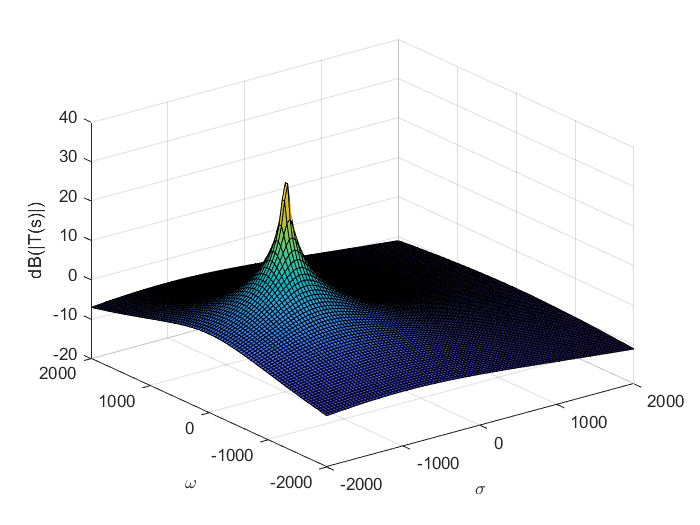

surf(sigma,omega,db(abs(TF)))
xlabel('\sigma')
ylabel('\omega')
zlabel('dB(|T(s)|)')

## Logaritmic Scaling: y axis

However, assuming we wish to study values of $\omega \in \left\lbrack {10}^{-2} ,{10}^{\;4} \right\rbrack$, it may be beneficial to generate $\omega$ using a logarithmic sampling instead of a linear sampling.

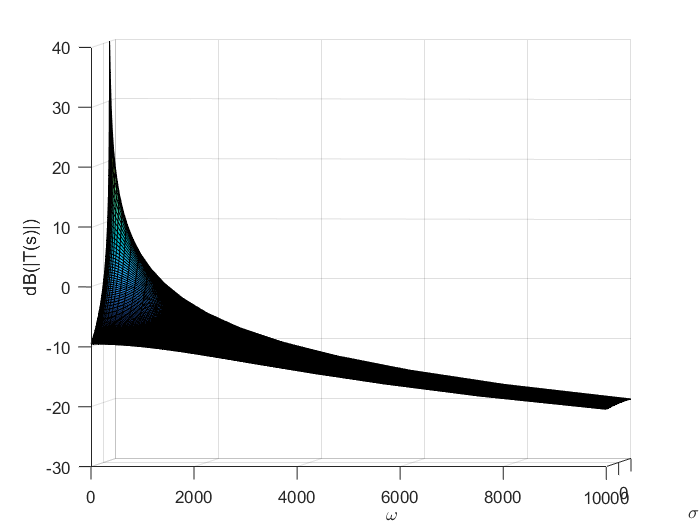

omega = logspace(-2,4);

s = sigma+1j*omega';
TF = 1./(R*C*s+1);

figure
surf(sigma,omega,db(abs(TF)))
xlabel('\sigma')
ylabel('\omega')
zlabel('dB(|T(s)|)')

Looking at the graph, we see that the difference between two successive points in our $\omega$ grid gets smaller as $\omega$ itself gets smaller. However, the graph is still not very easy to read. 

To improve readibility, we not only generate $\omega$ using a logarithmic scaling, we are also going to plot our figure using a logaritmic scaling on the $\omega$ axis. 

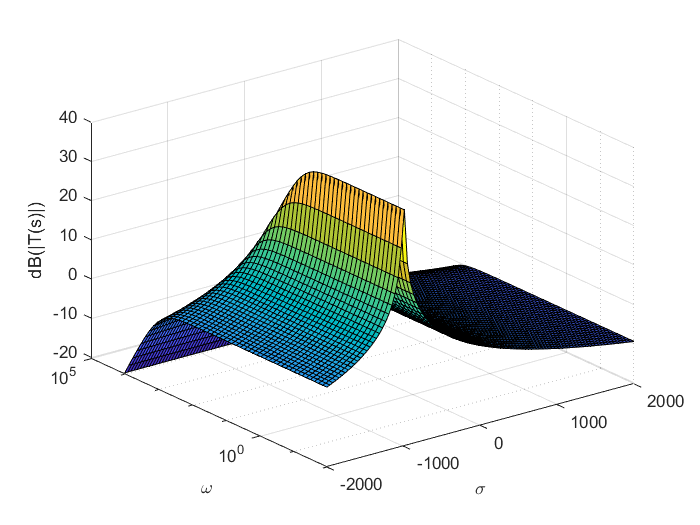

figure
surf(sigma,omega,db(abs(TF)))
set(gca, 'YScale', 'log');
xlabel('\sigma')
ylabel('\omega')
zlabel('dB(|T(s)|)')

## Frequency Response

Given an input $u\left(t\right)=U_0 \;\cos \left(\omega t+\varphi \right)$, where $U_0$ is the amplitude and $\varphi \;$is the phase, it can be shown that our output is going to satisfy 

$v\left(t\right)=V_0 \;\cos \left(\omega t+\psi \right)$,

with


$$V_0 =|T\left(j\omega \right)|U_0$$


and

$\psi =\angle \;\left\lbrace T\left(j\omega \right)\right\rbrace +\varphi$,

where $\angle \;\left\lbrace T\left(s\right)\right\rbrace$ denotes the phase of $T\left(s\right)$. For now, we are going to focus on the norm and leave all phase considerations to future examples. Since $s=\sigma +j\omega$, all we need to do is focus on what happens on the line $\sigma =0$. 

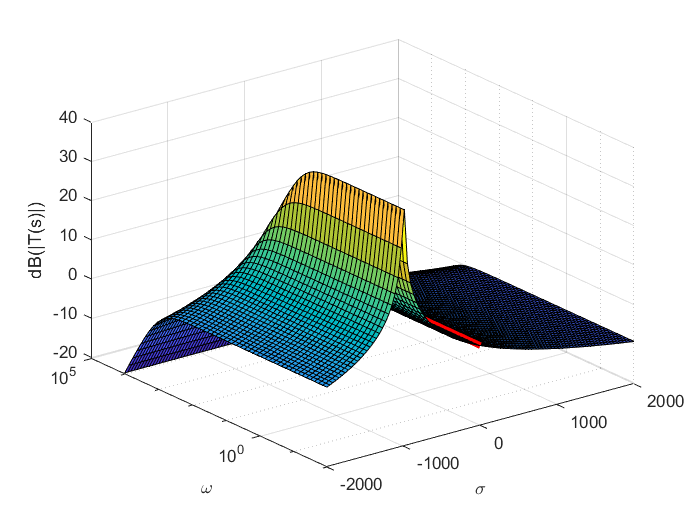

figure % Same as previous
surf(sigma,omega,db(abs(TF)))
set(gca, 'YScale', 'log');
xlabel('\sigma')
ylabel('\omega')
zlabel('dB(|T(s)|)')


hold on % We now add a red line where sigma=0
s = 1j*omega;
TF = 1./(R*C*s+1);

plot3(zeros(size(TF)),omega,db(abs(TF)),'r','LineWidth',4)

This red line, which represents where $\textrm{dB}\left(|T\left(s\right)|\right)$ intersects the imaginary axis $s=j\omega$ is known as the Bode Plot.